clc;
clear;
close all;

%%%% Simulation Parameters %%%%
carrierFreq = 3.5e9; %3.5 GHz
wavelength = 1/carrierFreq;

% Location of Devices
gNB_position = [0, 0];
UE_position = [200, 0];
jammer_position = [200, 200];

% MIMO
Rx_num = 4;
Rx_distance = 3*wavelength/2;

fprintf('Rx antenna distance: %.2e\n', Rx_distance);

Rx antenna distance: 4.29e-10



Rx_total_size = Rx_num*Rx_distance;
fprintf('Rx size: %.2e\n', Rx_total_size);

Rx size: 1.71e-09



%%%% Noise & Path Loss %%%%
k = 1.38e-23; % Boltzmann constant (J/K)
T = 290; % Temperature (K)
F = 9; % Noise Figure (dB)
bandwidth = 100e6; % Bandwidth (Hz)
noisePower_dBm = 10*log10(k * T * bandwidth * 10^(F/10)); % Thermal noise power (dBm)

% Path Loss Model (Simple Free-Space Path Loss)
d = norm(UE_position - gNB_position); % Distance between gNB and UE
pathLoss_dB = 20*log10(d) + 20*log10(carrierFreq) - 147.55; % Free-space path loss

%%%% Signal Power %%%%
transmitPower_dBm = 25;  % gNB Signal Power
receivedPower_dBm = transmitPower_dBm - pathLoss_dB; % UE Signal Power

%set jammer power
jammerPower_dBm = 1+(transmitPower_dBm-1)*rand();

jammerPath_dBm = 20*log(norm(jammer_position-gNB_position));
recievedJammer_dBm = jammerPower_dBm - jammerPath_dBm;

% Convert dBm to Watts
receivedPower_W = 10^(receivedPower_dBm/10)/1000;
noisePower_W = 10^(noisePower_dBm/10)/1000;
jammerPower_W = 10^(jammerPower_dBm/10)/1000;
recievedJammer_W = 10^(recievedJammer_dBm/10)/1000;

%%%% SNR (dB) %%%%
SNR_linear = receivedPower_W/noisePower_W;
SNR_dB = 10*log10(SNR_linear);

%%%% SINR (dB) %%%%
SINR_linear = receivedPower_W/(recievedJammer_W+noisePower_W);
SINR_dB = 10*log10(SINR_linear);

%%%% Throughput (Shannon-Hartley) %%%%
throughput_bps = bandwidth * log2(1 + SNR_linear);

%%%% Bit Error Rate %%%%
EbN0_linear = SINR_linear/(bandwidth/1e6);
BER = 0.5*erfc(sqrt(EbN0_linear))

BER = 3.3315e-50

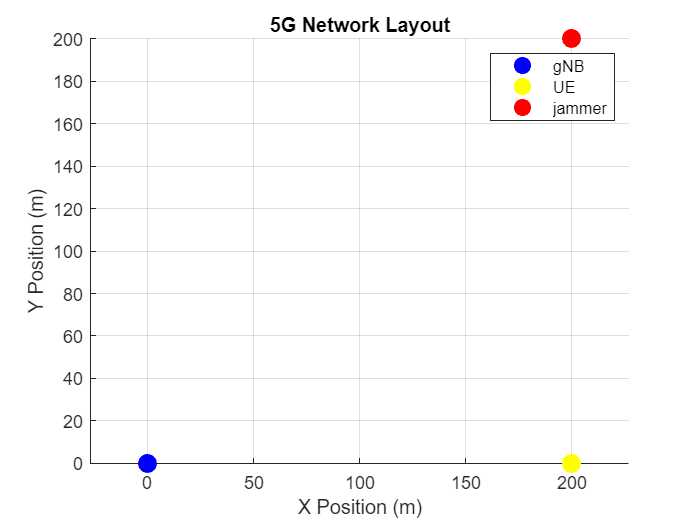


%%%% Setup Devices %%%%
gNB = struct('Position', gNB_position, 'Power', transmitPower_dBm);
UE = struct('Position', UE_position, 'PowerReceived', receivedPower_dBm, 'SNR_dB', SNR_dB, 'SINR_dB', SINR_dB, 'Throughput_bps', throughput_bps, 'BER', BER);
jammer = struct('Position', jammer_position, 'Power', jammerPower_dBm, 'Recieved_Power', recievedJammer_dBm);

% angle calculation
jammer_gNB_theta = atan((jammer.Position(2)-gNB.Position(2))/(jammer.Position(1)-gNB.Position(1)));

%%%% 5G Network Layout Visual %%%%
figure;
hold on;
plot(gNB.Position(1), gNB.Position(2), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b'); % gNB
plot(UE.Position(1), UE.Position(2), 'yo', 'MarkerSize', 10, 'MarkerFaceColor', 'y'); % UE
plot(jammer.Position(1), jammer.Position(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); % jammer
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('5G Network Layout');
legend('gNB', 'UE', 'jammer');
grid on;
axis equal;

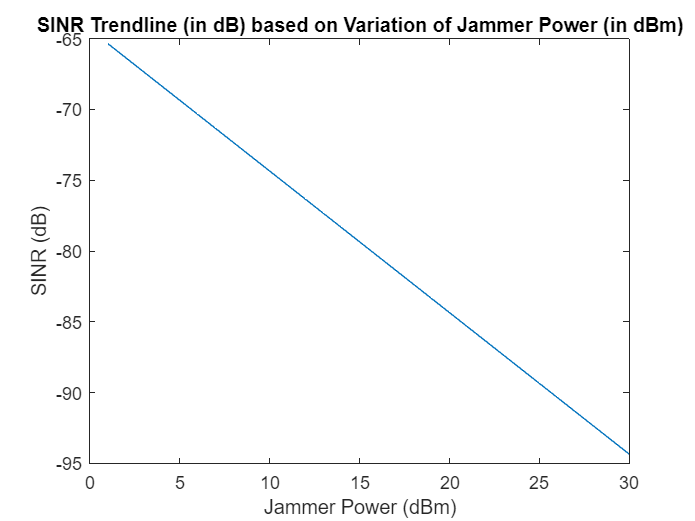


%%%% SINR vs. Jammer Power %%%%
jammerPower_dBm_range = 1:1:30;
correlated_SINR_range = zeros(size(jammerPower_dBm_range));

for i = 1:length(jammerPower_dBm_range)
    jammerValue_dBm = jammerPower_dBm_range(i);
    jammerValue_W = 10^(jammerValue_dBm/10)/1000;

    SINR_Value = receivedPower_W/(jammerValue_W+noisePower_W);
    correlated_SINR_range(i) = 10*log10(SINR_Value);
end

figure;
plot(jammerPower_dBm_range, correlated_SINR_range);
title('SINR Trendline (in dB) based on Variation of Jammer Power (in dBm)');
xlabel('Jammer Power (dBm)');
ylabel('SINR (dB)');


%%%% BER vs. SINR %%%%
SINR_dB_range = -10:1:30;
SINR_linear_range = 10.^(SINR_dB_range / 10)

SINR_linear_range = 1.0e+03 *

    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0005    0.0006    0.0008    0.0010    0.0013    0.0016    0.0020    0.0025    0.0032    0.0040    0.0050    0.0063    0.0079    0.0100    0.0126    0.0158    0.0200    0.0251    0.0316    0.0398    0.0501    0.0631    0.0794    0.1000    0.1259    0.1585    0.1995    0.2512    0.3162    0.3981    0.5012    0.6310    0.7943    1.0000


EbN0_linear_val = SINR_linear_range/(bandwidth/1e6);
BER_range = 0.5*erfc(sqrt(EbN0_linear_val))

BER_range =     0.4822    0.4800    0.4776    0.4748    0.4717    0.4683    0.4644    0.4601    0.4553    0.4498    0.4438    0.4370    0.4293    0.4208    0.4113    0.4007    0.3889    0.3758    0.3612    0.3451    0.3274    0.3079    0.2867    0.2638    0.2392    0.2132    0.1861    0.1584    0.1306    0.1038    0.0786    0.0563    0.0375    0.0229    0.0125    0.0060    0.0024    0.0008    0.0002    0.0000    0.0000



figure;
semilogy(SINR_dB_range, BER_range);
title('BER vs. SINR');
xlabel('SINR (dB)');
ylabel('Bit Error Rate (BER)');
grid on;

%%%% Calculated Values Display %%%%
fprintf('gNB Transmit Power: %.2f dBm\n', gNB.Power);

gNB Transmit Power: 25.00 dBm


fprintf('Distance between gNB and UE: %.2f meters\n', d);

Distance between gNB and UE: 200.00 meters


fprintf('Path Loss (dB): %.2f dB\n', pathLoss_dB);

Path Loss (dB): 89.35 dB


fprintf('Jammer Power (dB): %.2f dB\n', jammer.Power);

Jammer Power (dB): 7.68 dB


fprintf('Jammer Recieved (dB): %.2f dB\n', jammer.Recieved_Power);

Jammer Recieved (dB): -105.21 dB


fprintf('Received Power at UE: %.2f dBm\n', UE.PowerReceived);

Received Power at UE: -64.35 dBm


fprintf('Noise Power: %.2f dBm\n', noisePower_dBm);

Noise Power: -114.98 dBm


fprintf('SNR at UE: %.2f dB\n', UE.SNR_dB);

SNR at UE: 50.63 dB


fprintf('SINR at UE: %.2f dB\n', UE.SINR_dB);

SINR at UE: 40.43 dB


fprintf('Throughput at UE: %.2f bps (%.2f Mbps)\n', UE.Throughput_bps, UE.Throughput_bps / 1e6);

Throughput at UE: 1681736261.89 bps (1681.74 Mbps)


fprintf('Angle from Jammer to gNB: %.2f \n', jammer_gNB_theta);

Angle from Jammer to gNB: 0.79 


fprintf('Bit Error Rate (BER): %.2e\n', UE.BER);

Bit Error Rate (BER): 3.33e-50



%%%% Link Quality %%%%
linkQualityThreshold = -95; % dBm -- minimum required signal strength for reliable connection
if UE.PowerReceived >= linkQualityThreshold
    disp('Connection Successful: UE is able to receive the signal.');
else
    disp('Connection Failed: UE cannot receive the signal.');
end

Connection Successful: UE is able to receive the signal.


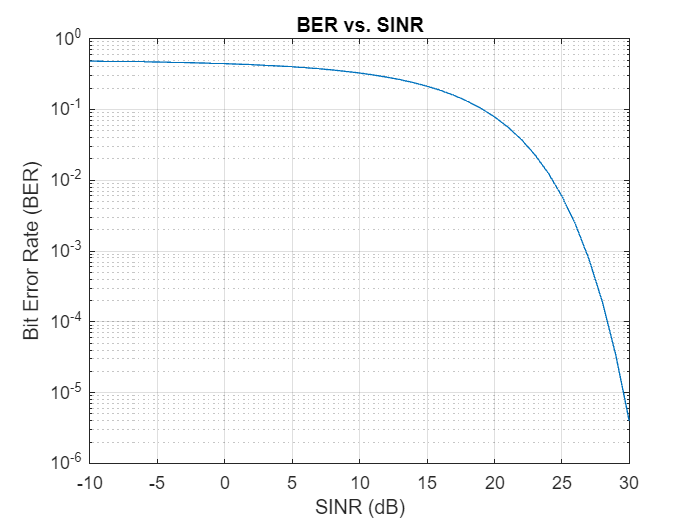


hold off;